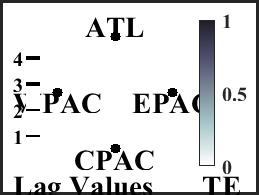

% ---------------- LOAD DATA
clear
% sys_name can be Dataset_A, Dataset_B, Dataset_D
%                            Dataset_B2, Dataset_D2
%                            PWC, BCT
% ------- to be changed accordingly
sys_name = "PWC";
method = "TE"; % TE or pTE or GC
pdf = "kde"; % kde or binning
max_lag = 4;

% location path to data
loc = "G:\My Drive\Backup_01_Mar_23\MatlabCodes\Data\RobustnessCheck\";
sys = load(strcat(loc,sys_name,".mat")); % sys should contain all_var and varnames
% --------------- CAUSAL ANALYSES
switch method
    case "pTE"
        res = pTE_fun(sys.all_var,max_lag,"kde_trnsf","on")
    case "TE"
        res = TE_fun(sys.all_var,max_lag,"pdf",pdf);
    otherwise
        disp("Undefined Method")
end

% --------------- PLOTTING
% Whole plot
[f,ax] = network_plot(res.max_str,res.lag_val,max_lag,"stat_name",method, ...
    "varnames",sys.varnames);
filename = strcat(loc,"Figures\1_TE.jpg");
exportgraphics(f,filename)

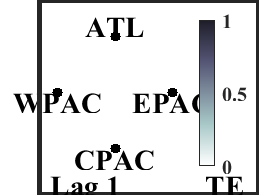

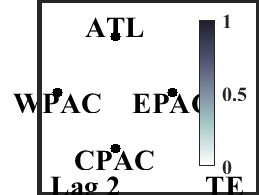

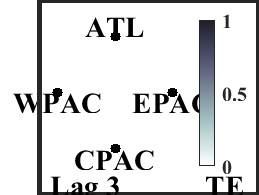

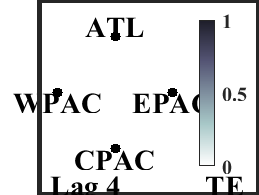


% lag wise plot
clim = ax(1).CLim;
for l_lags = 1:max_lag
    f = network_plot(res.true_links(:,:,l_lags),[],l_lags, ...
        "varnames",sys.varnames,"clim",clim,"stat_name",method);
    filename = strcat(loc,"Figures\2_TE_", mat2str(l_lags),".jpg");
    exportgraphics(f,filename)
end


% ------------ CONSISTENCY CHECK
all_mat = consistency_check(sys.all_var, max_lag, ...
    "len_sample",200,"method",method,"pdf",pdf,"kde_trnsf","on");

ans =
    20
ans =
    50
ans =
    30
ans =
    40
ans =
    10
ans =
    80
ans =
    70
ans =
    60
ans =
    90
ans =
   100


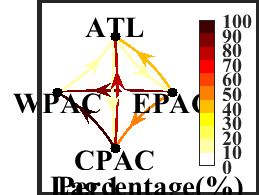

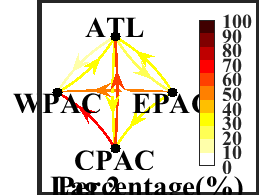

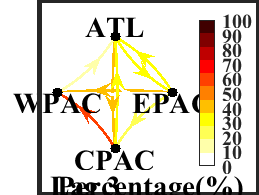

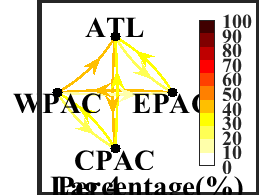

per_mat = (sum(logical(all_mat),4)/size(all_mat,4)) * 100;
% plotting
cmap = hot(11);
cmap = cmap(11:-1:1,:);
for l_lags = 1:max_lag
    f = network_plot(per_mat(:,:,l_lags),[],l_lags, ...
        "varnames",sys.varnames,"clim",[0 100],"cmap",cmap,"TickLabels",0:10:100, ...
        "stat_name","Percentage(%)");
    filename = strcat(loc,"Figures\4_TE_", mat2str(l_lags),".jpg");
    exportgraphics(f,filename)
end

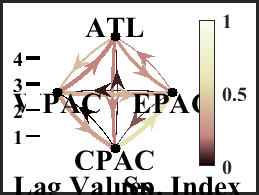


% --------------- SPURIOUSNESS INDEX
sp_idx = nan(size(per_mat,1),size(per_mat,2));
[max_per,lag_per] = max(per_mat,[],3); 
for i = 1:size(per_mat,1)
    for j = 1:size(per_mat,2)
        if i ~= j && max_per(i,j)
            sp_idx(i,j) = -log(max_per(i,j)/100)/log(100);
        else
            sp_idx(i,j) = 1;
        end
    end
end
% plotting
figure
aa = pink;
cm = [aa(1,:);aa(100,:);aa(190,:);aa(245,:)];
map = interp1([0;20;60;100], cm, (0:100));
f = network_plot(sp_idx,lag_per,max_lag,"stat_name","Sp. Index", ...
    "varnames",sys.varnames,"cmap",map,"clim",[0 1]);
filename = strcat(loc,"Figures\3_TE.jpg");
exportgraphics(f,filename)